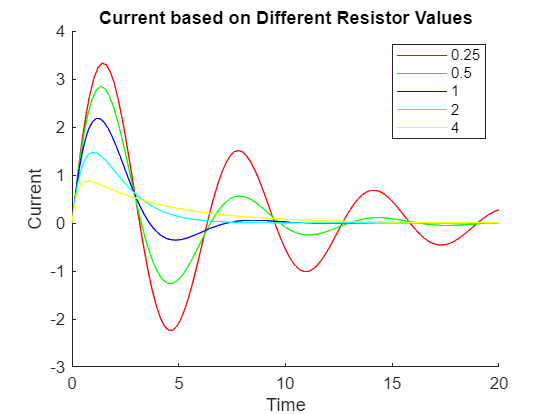

L = 1;
C = 1;
I0 = 0;            
dIdt0 = 4;
tspan = [0 20];

y0 = [I0, dIdt0];

% dI/dt = v1
% d^2I/dt^2 = (-R/L) * v1 - (1/(L*C)) * I

R025 = 0.25;
odefun025 = @(t, y) [y(2); (-R025/L)*y(2) - (1/(L*C))*y(1)];

R05 = 0.5;
odefun05 = @(t, y) [y(2); (-R05/L)*y(2) - (1/(L*C))*y(1)];

R1 = 1;
odefun1 = @(t, y) [y(2); (-R1/L)*y(2) - (1/(L*C))*y(1)];

R2 = 2;
odefun2 = @(t, y) [y(2); (-R2/L)*y(2) - (1/(L*C))*y(1)];

R4 = 4;
odefun4 = @(t, y) [y(2); (-R4/L)*y(2) - (1/(L*C))*y(1)];

[x025, y025] = ode45(odefun025, tspan, y0);
[x05, y05] = ode45(odefun05, tspan, y0);
[x1, y1] = ode45(odefun1, tspan, y0);
[x2, y2] = ode45(odefun2, tspan, y0);
[x4, y4] = ode45(odefun4, tspan, y0);

figure;
hold on;
title('Current based on Different Resistor Values');
xlabel('Time');
ylabel('Current');

plot(x025, y025(:,1), 'r', 'DisplayName', '0.25');
plot(x05, y05(:,1), 'g', 'DisplayName', '0.5');
plot(x1, y1(:,1), 'b', 'DisplayName', '1');
plot(x2, y2(:,1), 'c', 'DisplayName', '2');
plot(x4, y4(:,1), 'y', 'DisplayName', '4');

legend;
hold off;

%MATLAB Basics (50%)
% Knowledge tested: You’ll need strong proficiency in basic MATLAB operations, working with matrices, loops, conditionals, and basic functions.

% Key Concepts:

%   Creating and manipulating matrices
%   Basic mathematical operations
%   Conditional statements (if, else)
%   Loops (for, while)
%   Writing and using functions

%Code Example:

matlab
% Basic MATLAB example: creating and manipulating matrices
A = [1 2 3; 4 5 6; 7 8 9];  % 3x3 matrix
B = A';  % Transpose of A

% Conditional and loop example
for i = 1:5
    if mod(i, 2) == 0
        fprintf('%d is even\n', i);
    else
        fprintf('%d is odd\n', i);
    end
end

1 is odd


2 is even


3 is odd


4 is even


5 is odd


%2. Numerical Approximations in MATLAB (30%)
% Knowledge tested: Familiarity with numerical methods for approximating solutions, like finite differences and numerical integration.

% Key Topics:
%   Numerical differentiation
%   Numerical integration (trapz, quad)
%   Solving equations numerically (e.g., fzero, fminbnd)
%   Code Example (Numerical Integration):

matlab
% Define a function
f = @(x) x.^2;  % f(x) = x^2

% Numerical integration using trapezoidal rule
x = 0:0.1:5;
y = f(x);
area = trapz(x, y);  % Approximate area under the curve

% Numerical root finding example
root = fzero(@(x) x^2 - 4, 2);  % Find the root of f(x) = x^2 - 4

% Other Numerical Methods:
%   Forward, backward, and central differences for numerical derivatives
%   Solving ODEs with ode45 (often tested in this type of exam)

% Code Example (Solving ODE):

matlab
% Solve a first-order ODE: dy/dx = -2y, y(0) = 1
f = @(x, y) -2*y;
[x, y] = ode45(f, [0 5], 1);  % Solve from x = 0 to 5

% Plot the solution
plot(x, y);
xlabel('x');
ylabel('y');
title('Solution of ODE dy/dx = -2y');

% 3. Solving Differential Equations in Simulink (20%)
% Knowledge tested: Understanding of how to model systems in Simulink, particularly differential equations, using integrators, summation blocks, gains, etc.
% Key Concepts:

% Building models for first-order and second-order differential equations
% Understanding how to use blocks like integrators, gain, and sum
% Setting initial conditions and simulation parameters
% Visualizing results using the Scope block
% Example (Simulink Workflow):

Convert the differential equation 
𝑑
𝑦
𝑑
𝑡
+
3
𝑦
=
0
dt
dy
�
 +3y=0 into a block diagram using Simulink:
Place an Integrator block for 
𝑦
(
𝑡
)
y(t)
Add a Gain block with value -3
Use a Sum block to model 
𝑑
𝑦
𝑑
𝑡
+
3
𝑦
=
0
dt
dy
�
 +3y=0
Use a Scope block to view the output of 
𝑦
(
𝑡
)
y(t)
Summary of Topics for Exam Preparation:
MATLAB Basics:

Matrix operations, loops, conditionals, function creation
Practice manipulating arrays and simple program structures
Numerical Methods:

Numerical integration (trapz, quad), root finding (fzero)
ODE solvers (ode45, ode23) for initial value problems
Simulink Models:

Building models to represent differential equations
Understanding how to use key blocks (Integrator, Gain, Sum, Scope)
Setting up and running simulations with initial conditions
These are the key skills and concepts you’ll need to practice based on the exam topics. Let me know if you need more detailed examples or help with specific areas!